

clear all
close all
%read data
depth2_6 = readmatrix("2,6variation.xlsx");
% depth2_7 = readmatrix("2,7variation.xlsx");
% depth2_8 = readmatrix("2,8variation.xlsx");
% depth2_9 = readmatrix("2,9variation.xlsx");
% depth3_6 = readmatrix("3,6variation.xlsx");
% depth3_7 = readmatrix("3,7variation.xlsx");
% depth3_8 = readmatrix("3,8variation.xlsx");
% depth3_9 = readmatrix("3,8variation.xlsx");

%Group dataset to matrix

## trial for stacking columns

% stack the values as a very large column
% qfactor_2_6 = depth2_6(:, 9);
% resonance_2_6 = depth2_6(:, 8);
% intervals_2_6 = depth2_6(:, 3);
% polywidth_2_6 = depth2_6(:, 4);

## old version

qfactor_2_6 = zeros(10,7);
for i = 1:7
    qfac = depth2_6((10*i-9):10*i, 9);
    qfactor_2_6(:,i) = qfac;
end

resonance_2_6 = zeros(10,7);
for i = 1:7
    res_f = depth2_6((10*i-9):10*i, 8);
    resonance_2_6(:,i) = res_f;
end

intervals_2_6 = zeros(10,7);
for i = 1:7
    rot = depth2_6((10*i-9):10*i, 3);
    intervals_2_6(:,i) = rot;
end

polywidth_2_6 = zeros(10,7);
for i = 1:7
    dielectric_thickness = depth2_6((10*i-9):10*i, 4);
    polywidth_2_6(:,i) = dielectric_thickness;
end
% disp(resonance_2_6);

% polywidth = 0.1:0.1:1;
% interval = 20:5:50;
% sc = surfc(interval,polywidth,qfactor_2_6,'EdgeColor',"none",'FaceColor','interp');
% sc(2).ZLocation = 'zmax'
% sc(1).CData = resonance_2_6;
% h = gcf; % current figure handle
% hold off;


## test

% x = randi(50, 1, 50);                               % Create Data
% y = randi(50, 1, 50);
% z = randi(50, 1, 50);
% figure(1)
% scatter3(x, y, z, 'p')
% grid on;
% axis([0 50  0 50   0 50])
% title('Original Data')
% m = (z<50) & (z>25);                            % Select Data (Logical Vector)
% figure(2)
% xrestrict = x(m);
% disp(xrestrict);
% yrestrict = y(m);
% disp(yrestrict);
% zrestrict = z(m);
% disp(zrestrict);
% scatter3(x(m), y(m), z(m), 'p')
% grid on;
% axis([0 50  0 50   0 50])
% title('Selected Data')


## other



% ch = get(gca,'ch');
% x = get(ch,'xd');
% y = get(ch,'yd');
% z = get(ch,'zd');
% x = sc(1).XData;
% disp(x);
% disp(y);
% disp(z);
% v = meshgrid(resonance_2_6, resonance_2_6);
% 
% [x, y, z] = meshgrid(interval, polywidth, qfactor_2_6);
% [xi,yi,zi] = meshgrid(.1:.25:10, -3:.25:3, -3:.25:3);
% vi = interp3(x,y,z,v,xi,yi,zi); % V is 31-by-41-by-27
% slice(xi,yi,zi,vi,[6 9.5],2,[-2 .2])

% x = linspace(-1,1,16); y =linspace(-1,1,40); z = linspace(-1,1,3); 
% [X,Y,Z] = meshgrid(x,y,z);
% V = sin(X)+cos(Y)+Z.^2; % some function 
% xi = linspace(-0.5,1,16); yi = linspace(-0.8,0.8,79); zi = linspace(-1,1,9); 
% [Xi,Yi,Zi] = meshgrid(xi,yi,zi); 
% vi = interp3(X,Y,Z,V, Xi, Yi, Zi)
% slice(xi,yi,zi,vi,[1 8],[1 20],[1 1.5])


## version 2. 6

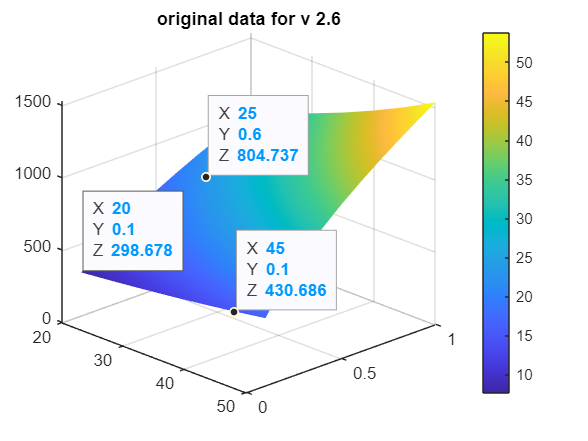

% c = contour3(interval, polywidth, qfactor_2_6);
% sc(1).CData = resonance_2_6;
% sc(2).ZLocation = 'zmax';
polywidth = 0.1:0.1:1;
interval = 20:5:50;
% sc = surfc(interval,polywidth,qfactor_2_6,'EdgeColor',"none",'FaceColor','interp')
sc = surf(interval, polywidth, resonance_2_6, 'EdgeColor', "none", 'FaceColor', 'interp');
sc.CData = qfactor_2_6;
hold on;
% c = contour3(interval, polywidth, resonance_2_6, 40);
title('original data for v 2.6');
colorbar;
hold off;

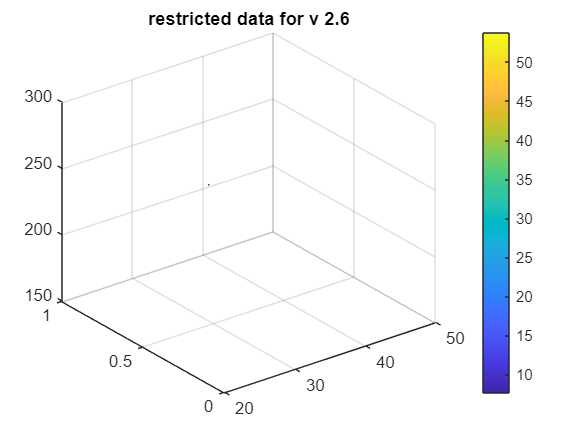


polywidth = 0.1:0.1:1;
interval = 20:5:50;
% sc = surfc(interval,polywidth,qfactor_2_6,'EdgeColor',"none",'FaceColor','interp')
sc = surf(interval, polywidth, resonance_2_6, 'EdgeColor', "none", 'FaceColor', 'interp');
sc.CData = qfactor_2_6;
hold on;
% c = contour3(interval, polywidth, resonance_2_6, 40);
zlim([150 500]);
title('restricted data for v 2.6');
colorbar;
hold off;

## restrict the values

max = 500;
min = 185;
restrict = (resonance_2_6 < max) & (resonance_2_6 > min);
xrestrict = intervals_2_6(restrict);
% transpose the yrestrict
% xrestrict = xrestrict.';
% disp(xrestrict);

yrestrict = polywidth_2_6(restrict);
% disp(yrestrict);

zrestrict = qfactor_2_6(restrict);
% disp(zrestrict);

resonancerestrict = resonance_2_6(restrict);

concate_col = [xrestrict yrestrict zrestrict];



## IDK WHAT IS BEING DONE RN - ITERATION 2

% iteration 2 is above

## stack the xrestrict by the columns and the yrestrict by the rows

%       [x_0 ... x_n]       [y_0 y_0 ... y_0]
% x:    [... ... ...]  y:   [... ... ... ...]
%       [x_0 ... x_n]       [y_n y_n ... y_n]
qfac_length = length(qfactor_2_6);
% xstack = xrestrict;
% ystack = yrestrict;
% 
% xsingle = xrestrict;
% ysingle = yrestrict;  
% for i = 1:qfac_length-1
%     xstack = [xstack; xsingle];
%     ystack = [ystack ysingle]
%     
% end

## stack the x and y restricted vectors with meshgrid

% use meshgrid to stack columns and rows
% transpose the restrict vectors
% xrestrict = xrestrict.';
% yrestrict = yrestrict.';
% zrestrict = zrestrict.';
% zrestrict = diag(zrestrict);
% [xrestrict, yrestrict, temp] = meshgrid(xrestrict, yrestrict, 0);

## compare

x = 2*rand(2500,1) - 1; 
y = 2*rand(2500,1) - 1; 
z = 2*rand(2500,1) - 1;
v = x.^2 + y.^3 - z.^4;
d = -1:0.05:1;
[xq,yq,zq] = meshgrid(d,d,0);
vq = griddata(x,y,z,v,xq,yq,zq);
disp(zq);
% plot3(x,y,v,'ro')
% hold on
surf(xq,yq,vq)


## ariel version

% vi = griddata(xrestrict, yrestrict, zrestrict, resonancerestrict, intervals_2_6, polywidth_2_6, qfactor_2_6); 
% vi = griddata(intervals_2_6, polywidth_2_6, qfactor_2_6, resonance_2_6, xrestrict, yrestrict, zrestrict); 
% [xrestrict, yrestrict, zrestrict] = meshgrid(xrestrict, yrestrict, 200);
% polywidth = 0.1:0.1:1;
% interval = 20:5:50;
% [xrestrict, yrestrict, zrestrict] = meshgrid(interval, polywidth, 0);

vi = griddata(intervals_2_6, polywidth_2_6, resonance_2_6, qfactor_2_6, xrestrict, yrestrict, zrestrict); 
hold off;  



% mesh(xrestrict, yrestrict, vi);
% plot3(intervals_2_6, polywidth, qfactor_2_6, 'o');
% plot3(xrestrict, yrestrict, vi);
% tri = delaunay(xrestrict, yrestrict);
% trisurf(tri, xrestrict, yrestrict, vi);

plot3(xrestrict, yrestrict, vi, 'o');
colorbar;
xlabel('Density(um)')
ylabel('Dielectric Width(um)')
zlabel('Resonance')
title('data for v 2.6')
% surf(xrestrict, yrestrict, vi);
% surf(X, Y, vi);
% sc = surf(xrestrict, yrestrict, vi);
% F = griddedInterpolant(xrestrict, yrestrict, zrestrict);
% 
% resonancerestrict = resonance_2_6(restrict);
% 
% interpolated_values = interp3(xrestrict, yrestrict, zrestrict, resonancerestrict, 1, 0.1, 1);

% sc = surf(intervals_2_6(restrict), polywidth_2_6(restrict), qfactor_2_6(restrict), 'EdgeColor', "none", 'FaceColor', 'interp');
sc.CData = resonance_2_6;
hold on;
c = contour3(interval, polywidth, qfactor_2_6, 50);
title('Original data for v 2.6');

hold off；






%Plot
polywidth = 0.1:0.1:1;
interval = 20:5:50;
% sc = surfc(interval,polywidth,qfactor_2_6,'EdgeColor',"none",'FaceColor','interp');
sc = surf(interval,polywidth,qfactor_2_6,'EdgeColor',"none",'FaceColor','interp');
sc.CData = resonance_2_6;
hold on;
c = contour3(interval, polywidth, qfactor_2_6, 30);

hold off;

polywidth = 0.1:0.1:1;
interval = 20:5:50;
% sc = surfc(interval,polywidth,qfactor_2_6,'EdgeColor',"none",'FaceColor','interp');
sc = surf(interval,polywidth,qfactor_2_6,'EdgeColor',"none",'FaceColor','interp');
sc.CData = resonance_2_6;
hold on;
c = contour3(interval, polywidth, qfactor_2_6, 20);


polywidth = 0.1:0.1:1;
interval = 20:5:50;
sc = surfc(interval,polywidth,qfactor_2_6,'EdgeColor',"none",'FaceColor','interp');

% sc = surf(interval,polywidth,qfactor_2_6,'EdgeColor',"none",'FaceColor','interp');
sc(2).ZLocation = 'zmax'
sc(1).CData = resonance_2_6;
% c = contour3(interval, polywidth, qfactor_2_6);
% sc(1).CData = resonance_2_6;
% sc(2).ZLocation = 'zmax';


zlim([0 60])
caxis([0 1600])
cb = colorbar;
xlabel('Density(um)')
ylabel('Dielectric Width(um)')
zlabel('Q factor')
ylabel(cb,'Resonance Frequency(MHz)')
colormap(jet)
title('Hilbert Depth 2, turn 6')

%Group dataset to matrix
qfactor_2_7 = zeros(10,7);
for i = 1:7
    qfac = depth2_7((10*i-9):10*i,9);
    qfactor_2_7(:,i) = qfac;
end
resonance_2_7 = zeros(10,7);
for i = 1:7
    res_f = depth2_7((10*i-9):10*i,8);
    resonance_2_7(:,i) = res_f;
end

%Plot
polywidth = 0.1:0.1:1;
interval = 20:5:50;
sc = surfc(interval,polywidth,qfactor_2_7,'EdgeColor',"none",'FaceColor','interp');
sc(2).ZLocation = 'zmax';
sc(1).CData = resonance_2_7;

zlim([0 60])
caxis([0 1600])
cb = colorbar;
xlabel('Density(um)')
ylabel('Dielectric Width(um)')
zlabel('Q factor')
ylabel(cb,'Resonance Frequency(MHz)')
colormap(jet)
% colormap(jet(7))
title('Hilbert Depth 2, turn 7')

%Group dataset to matrix
qfactor_2_8 = zeros(10,7);
for i = 1:7
    qfac = depth2_8((10*i-9):10*i,9);
    qfactor_2_8(:,i) = qfac;
end
resonance_2_8 = zeros(10,7);
for i = 1:7
    res_f = depth2_8((10*i-9):10*i,8);
    resonance_2_8(:,i) = res_f;
end

%Plot
polywidth = 0.1:0.1:1;
interval = 20:5:50;
sc = surfc(interval,polywidth,qfactor_2_8,'EdgeColor',"none",'FaceColor','interp');
sc(2).ZLocation = 'zmax';
sc(1).CData = resonance_2_8;
zlim([0 60])
caxis([0 1600])
cb = colorbar;
xlabel('Density(um)')
ylabel('Dielectric Width(um)')
zlabel('Q factor')
ylabel(cb,'Resonance Frequency(MHz)')
colormap(jet)
% colormap(jet(7))
title('Hilbert Depth 2, turn 8')

%Group dataset to matrix
qfactor_2_9 = zeros(10,7);
for i = 1:7
    qfac = depth2_9((10*i-9):10*i,9);
    qfactor_2_9(:,i) = qfac;
end
resonance_2_9 = zeros(10,7);
for i = 1:7
    res_f = depth2_9((10*i-9):10*i,8);
    resonance_2_9(:,i) = res_f;
end

%Plot
polywidth = 0.1:0.1:1;
interval = 20:5:50;
sc = surfc(interval,polywidth,qfactor_2_9,'EdgeColor',"none",'FaceColor','interp');
sc(2).ZLocation = 'zmax';
sc(1).CData = resonance_2_9;
zlim([0 60])
caxis([0 1600])
cb = colorbar;
xlabel('Density(um)')
ylabel('Dielectric Width(um)')
zlabel('Q factor')
ylabel(cb,'Resonance Frequency(MHz)')
colormap(jet)
% colormap(jet(7))
title('Hilbert Depth 2, turn 9')

%Group dataset to matrix
qfactor_3_6 = zeros(10,7);
for i = 1:7
    qfac = depth3_6((10*i-9):10*i,9);
    qfactor_3_6(:,i) = qfac;
end
resonance_3_6= zeros(10,7);
for i = 1:7
    res_f = depth3_6((10*i-9):10*i,8);
    resonance_3_6(:,i) = res_f;
end

%Plot
polywidth = 0.1:0.1:1;
interval = 20:5:50;
sc = surfc(interval,polywidth,qfactor_3_6,'EdgeColor',"none",'FaceColor','interp');
sc(2).ZLocation = 'zmax';
sc(1).CData = resonance_3_6;
zlim([0 60])
caxis([0 1600])
cb = colorbar;
xlabel('Density(um)')
ylabel('Dielectric Width(um)')
zlabel('Q factor')
ylabel(cb,'Resonance Frequency(MHz)')
colormap(jet)
% colormap(jet(7))
title('Hilbert Depth 3, turn 6')

%Group dataset to matrix
qfactor_3_7 = zeros(10,7);
for i = 1:7
    qfac = depth3_7((10*i-9):10*i,9);
    qfactor_3_7(:,i) = qfac;
end
resonance_3_7= zeros(10,7);
for i = 1:7
    res_f = depth3_7((10*i-9):10*i,8);
    resonance_3_7(:,i) = res_f;
end

%Plot
polywidth = 0.1:0.1:1;
interval = 20:5:50;
sc = surfc(interval,polywidth,qfactor_3_7,'EdgeColor',"none",'FaceColor','interp');
sc(2).ZLocation = 'zmax';
sc(1).CData = resonance_3_7;
zlim([0 60])
caxis([0 1600])
cb = colorbar;
xlabel('Density(um)')
ylabel('Dielectric Width(um)')
zlabel('Q factor')
ylabel(cb,'Resonance Frequency(MHz)')
colormap(jet)
% colormap(jet(7))
title('Hilbert Depth 3, turn 7')

%Group dataset to matrix
qfactor_3_8 = zeros(10,7);
for i = 1:7
    qfac = depth3_8((10*i-9):10*i,9);
    qfactor_3_8(:,i) = qfac;
end
resonance_3_8= zeros(10,7);
for i = 1:7
    res_f = depth3_8((10*i-9):10*i,8);
    resonance_3_8(:,i) = res_f;
end

%Plot
polywidth = 0.1:0.1:1;
interval = 20:5:50;
sc = surfc(interval,polywidth,qfactor_3_8,'EdgeColor',"none",'FaceColor','interp');
sc(2).ZLocation = 'zmax';
sc(1).CData = resonance_3_8;
zlim([0 60])
caxis([0 1600])
cb = colorbar;
xlabel('Density(um)')
ylabel('Dielectric Width(um)')
zlabel('Q factor')
ylabel(cb,'Resonance Frequency(MHz)')
colormap(jet)
% colormap(jet(7))
title('Hilbert Depth 3, turn 8')

%Group dataset to matrix
qfactor_3_9 = zeros(10,7);
for i = 1:7
    qfac = depth3_9((10*i-9):10*i,9);
    qfactor_3_9(:,i) = qfac;
end
resonance_3_9= zeros(10,7);
for i = 1:7
    res_f = depth3_9((10*i-9):10*i,8);
    resonance_3_9(:,i) = res_f;
end

%Plot
polywidth = 0.1:0.1:1;
interval = 20:5:50;
sc = surfc(interval,polywidth,qfactor_3_9,'EdgeColor',"none",'FaceColor','interp');
sc(2).ZLocation = 'zmax';
sc(1).CData = resonance_3_9;
zlim([0 60])
caxis([0 1600])
cb = colorbar;
xlabel('Density(um)')
ylabel('Dielectric Width(um)')
zlabel('Q factor')
ylabel(cb,'Resonance Frequency(MHz)')
colormap(jet)
% colormap(jet(7))
title('Hilbert Depth 3, turn 9')

depth4_6=readmatrix("4,6variation.xlsx");

qfactor_4_6 = zeros(10,4);
for i = 1:4
    qfac = depth4_6((10*i-9):10*i,9);
    qfactor_4_6(:,i) = qfac;
end
resonance_4_6= zeros(10,4);
for i = 1:4
    res_f = depth4_6((10*i-9):10*i,8);
    resonance_4_6(:,i) = res_f;
end

%Plot
polywidth = 0.1:0.1:1;
interval = 35:5:50;
sc = surfc(interval,polywidth,qfactor_4_6,'EdgeColor',"none",'FaceColor','interp');
sc(2).ZLocation = 'zmax';
sc(1).CData = resonance_4_6;
xlim([20 50])
zlim([0 60])
caxis([100 1600])
cb = colorbar;
xlabel('Density(um)')
ylabel('Dielectric Width(um)')
zlabel('Q factor')
ylabel(cb,'Resonance Frequency(MHz)')
colormap(jet)
% colormap(jet(7)) 
title('Hilbert Depth 4, turn 6')

depth4_7=readmatrix("4,7variation.xlsx");

qfactor_4_7 = zeros(10,3);
for i = 1:3
    qfac = depth4_7((10*i-9):10*i,9);
    qfactor_4_7(:,i) = qfac;
end
resonance_4_7= zeros(10,3);
for i = 1:3
    res_f = depth4_7((10*i-9):10*i,8);
    resonance_4_7(:,i) = res_f;
end

%Plot
polywidth = 0.1:0.1:1;
interval = 35:5:45;
sc = surfc(interval,polywidth,qfactor_4_7,'EdgeColor',"none",'FaceColor','interp');
sc(2).ZLocation = 'zmax';
sc(1).CData = resonance_4_7;
xlim([20 50])
zlim([0 60])
caxis([100 1600])
cb = colorbar;
xlabel('Density(um)')
ylabel('Dielectric Width(um)')
zlabel('Q factor')
ylabel(cb,'Resonance Frequency(MHz)')
colormap(jet)
% colormap(jet(7))
title('Hilbert Depth 4, turn 7')
